% Problem 1 (Generating Signals)
x=268

x = 268

a=1+mod(x,3)

a = 2

t=[-1:0.0001:1]

t =    -1.0000   -0.9999   -0.9998   -0.9997   -0.9996   -0.9995   -0.9994   -0.9993   -0.9992   -0.9991   -0.9990   -0.9989   -0.9988   -0.9987   -0.9986   -0.9985   -0.9984   -0.9983   -0.9982   -0.9981   -0.9980   -0.9979   -0.9978   -0.9977   -0.9976   -0.9975   -0.9974   -0.9973   -0.9972   -0.9971   -0.9970   -0.9969   -0.9968   -0.9967   -0.9966   -0.9965   -0.9964   -0.9963   -0.9962   -0.9961   -0.9960   -0.9959   -0.9958   -0.9957   -0.9956   -0.9955   -0.9954   -0.9953   -0.9952   -0.9951


y1=sin(20*pi*a*t)

y1 =     0.0000    0.0126    0.0251    0.0377    0.0502    0.0628    0.0753    0.0879    0.1004    0.1129    0.1253    0.1378    0.1502    0.1626    0.1750    0.1874    0.1997    0.2120    0.2243    0.2365    0.2487    0.2608    0.2730    0.2850    0.2970    0.3090    0.3209    0.3328    0.3446    0.3564    0.3681    0.3798    0.3914    0.4029    0.4144    0.4258    0.4371    0.4484    0.4596    0.4707    0.4818    0.4927    0.5036    0.5144    0.5252    0.5358    0.5464    0.5569    0.5673    0.5776


subplot(2,2,1)
plot(t,y1)
y2=cos((5*pi*a*t)+(pi/4))

y2 =     0.7071    0.7049    0.7026    0.7004    0.6982    0.6959    0.6937    0.6914    0.6891    0.6868    0.6845    0.6823    0.6800    0.6776    0.6753    0.6730    0.6707    0.6684    0.6660    0.6637    0.6613    0.6590    0.6566    0.6542    0.6518    0.6494    0.6471    0.6447    0.6423    0.6398    0.6374    0.6350    0.6326    0.6301    0.6277    0.6252    0.6228    0.6203    0.6179    0.6154    0.6129    0.6104    0.6079    0.6054    0.6029    0.6004    0.5979    0.5954    0.5929    0.5903


subplot(2,2,2)
plot(t,y2)
y3=exp(-2*a*t)

y3 =    54.5982   54.5763   54.5545   54.5327   54.5109   54.4891   54.4673   54.4455   54.4237   54.4020   54.3802   54.3584   54.3367   54.3150   54.2933   54.2715   54.2498   54.2281   54.2065   54.1848   54.1631   54.1414   54.1198   54.0982   54.0765   54.0549   54.0333   54.0117   53.9901   53.9685   53.9469   53.9253   53.9037   53.8822   53.8606   53.8391   53.8176   53.7960   53.7745   53.7530   53.7315   53.7100   53.6886   53.6671   53.6456   53.6242   53.6027   53.5813   53.5599   53.5384


subplot(2,2,3)
plot(t,y3)
y4=(exp(-1.*a.*t./4)).*sin(20.*pi.*t)

y4 =     0.0000    0.0104    0.0207    0.0311    0.0414    0.0518    0.0621    0.0725    0.0828    0.0931    0.1035    0.1138    0.1241    0.1344    0.1447    0.1550    0.1653    0.1756    0.1859    0.1962    0.2064    0.2167    0.2269    0.2372    0.2474    0.2576    0.2678    0.2780    0.2882    0.2983    0.3085    0.3186    0.3287    0.3389    0.3489    0.3590    0.3691    0.3791    0.3892    0.3992    0.4092    0.4192    0.4292    0.4391    0.4490    0.4589    0.4688    0.4787    0.4886    0.4984


subplot(2,2,4)
plot(t,y4)

%labelling the axis
subplot(2,2,1)
xlabel("t")
ylabel("y1(t)")
subplot(2,2,2)
xlabel("t")
ylabel("y2(t)")
subplot(2,2,3)
xlabel("t")
ylabel("y3(t)")
subplot(2,2,4)
xlabel("t")
ylabel("y4(t)")




% Problem 2 (Operation on user-defined functions)
a=1+mod(268,3)

a = 2

t=[-5:0.01:5]

t =    -5.0000   -4.9900   -4.9800   -4.9700   -4.9600   -4.9500   -4.9400   -4.9300   -4.9200   -4.9100   -4.9000   -4.8900   -4.8800   -4.8700   -4.8600   -4.8500   -4.8400   -4.8300   -4.8200   -4.8100   -4.8000   -4.7900   -4.7800   -4.7700   -4.7600   -4.7500   -4.7400   -4.7300   -4.7200   -4.7100   -4.7000   -4.6900   -4.6800   -4.6700   -4.6600   -4.6500   -4.6400   -4.6300   -4.6200   -4.6100   -4.6000   -4.5900   -4.5800   -4.5700   -4.5600   -4.5500   -4.5400   -4.5300   -4.5200   -4.5100


y=inline('exp(-2*t)','t')

y =

     Inline function:
     y(t) = exp(-2*t)



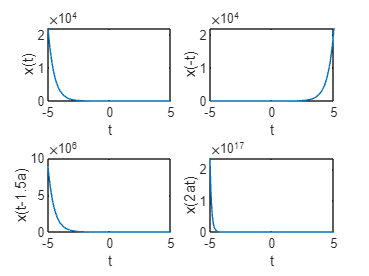

subplot(2,2,1)
plot(t,y(t))
subplot(2,2,2)
plot(t,y(-1*t))
subplot(2,2,3)
plot(t,y(t-(1.5*a)))
subplot(2,2,4)
plot(t,y(2*a*t))

%labelling the axis
subplot(2,2,1)
xlabel("t")
ylabel("x(t)")
subplot(2,2,2)
xlabel("t")
ylabel("x(-t)")
subplot(2,2,3)
xlabel("t")
ylabel("x(t-1.5a)")
subplot(2,2,4)
xlabel("t")
ylabel("x(2at)")

% Problem 3 (Importing Signals)

%importing ECG data
ECG_Data = importdata('ECG_Data.txt')

ECG_Data =     0.2284
    0.2240
    0.2206
    0.2163
    0.2111
    0.2059
    0.1998
    0.1964
    0.1938
    0.1886


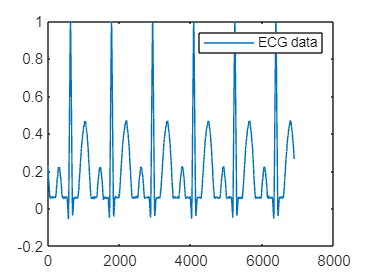

subplot(1,1,1)
plot(ECG_Data)
legend("ECG data")


% importing rainfall data
Rainfallindia_Jan = importdata('RainFallIndia_Jan.txt')

Rainfallindia_Jan =   107.3000
   43.7000
   32.7000
   42.2000
   33.3000
   28.0000
   42.2000
   42.2000
   83.7000
   70.3000


Rainfallindia_July = importdata('RainFallIndia_July.txt')

Rainfallindia_July = 1.0e+03 *

    0.2850
    0.4213
    0.4654
    0.6601
    0.9909
    0.2174
    0.8519
    0.6601
    0.2720
    0.4608



subplot(2,1,1)
histogram(Rainfallindia_Jan)
title('January Rainfall')


subplot(2,1,2)
histogram(Rainfallindia_July)
title('July Rainfall')

% Finding mean and standard deviation
mean_rainfall_Jan = mean(Rainfallindia_Jan)

mean_rainfall_Jan = 18.3513

mean_rainfall_July = mean(Rainfallindia_July)

mean_rainfall_July = 326.0936

standard_deviation_jan = std(Rainfallindia_Jan)

standard_deviation_jan = 21.0991

standard_deviation_july = std(Rainfallindia_July)

standard_deviation_july = 221.5326

jan_and_july_combined= [Rainfallindia_July;Rainfallindia_Jan]

jan_and_july_combined = 1.0e+03 *

    0.2850
    0.4213
    0.4654
    0.6601
    0.9909
    0.2174
    0.8519
    0.6601
    0.2720
    0.4608


mean_of_jan_and_july = mean(jan_and_july_combined)

mean_of_jan_and_july = 172.2224

std_of_jan_and_july = std(jan_and_july_combined)

std_of_jan_and_july = 220.0828


% playing audio, reads data from the file and returns sampled data
audio_data= importdata('track002.wav');
[y,Fs] = audioread('track002.wav'); 
%reads data from the file named filename, and returns sampled data, y, and a sample rate for that data, Fs.
sound(y,Fs);

% Problem 4 (amplitude Modulation)
a= 1+mod(268,3)
F=250.*a;
data = importdata('speech.wav')
[s, Fs1] = audioread('speech.wav')
y1 = fn(s, F, Fs1)
T = 1/Fs1
L=1500
t=(0:L-1)*T
y0= fft(y1)
s0=fft(s)
f =Fs1*(0:(L/2))/L;
P2 = abs(y0/L)
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
Q2 = abs(s0/L)
Q1 = Q2(1:L/2+1)
Q1(2:end-1) = 2*Q1(2:end-1)
subplot(2,2,1)
plot(y1)
subplot(2,2,2)
plot(s)
subplot(2,2,3);
plot(f, P1, 'blue', f, Q1, 'red')





% Problem 5 (Signal Generation-1)
Fs = 1000; % Sampling frequency (Hz)
alpha=1+mod(268,3)

alpha = 2

duration = 5; 
time_resolution = 0.001; % Time resolution(s)
frequency1 = 200*alpha; % First sinusoid frequency (Hz)
frequency2 = 220*alpha; % Second sinusoid frequency (Hz)

time = 0:time_resolution:duration-time_resolution;

sinusoidal1 = sin(2 * pi * frequency1 * time);
sinusoidal2 = sin(2 * pi * frequency2 * time);

signal = sinusoidal1 + sinusoidal2;
signal = signal / max(abs(signal));

filename = 'combined_sinusoids.wav';
audiowrite(filename, signal, Fs);

disp('Playing the generated audio...');

Playing the generated audio...


sound(signal, Fs);

% audio will finish playing
pause(duration + 1);

% Problem 6 (Signal Generation-2)
Fs = 44100; % Sampling frequency (Hz)
duration = 0.5; % Duration of each note (s)

% Frequencies for "Do Re Mi Fa So La Ti Do"
frequencies = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25]; % Hz

sequence = [];

for f = frequencies
    t = 0:1/Fs:duration;
    note_signal = sin(2 * pi * f * t);
    sequence = [sequence, note_signal];
end

filename = 'do_re_mi_fa_so_la_ti_do.wav';
audiowrite(filename, sequence, Fs);

disp('Playing the generated audio...');

Playing the generated audio...


sound(sequence, Fs);

% audio will finish playing
pause(length(sequence) / Fs + 1);



% Problem 7 (Convolution)
[trackData, trackFs] = audioread('Track002.wav');

convData = load('ConvFile2.txt');

convData = convData / norm(convData);

convResult = conv(trackData, convData);

filename = 'convolution_result.wav';
audiowrite(filename, convResult, trackFs);

disp('Playing the original audio...');

Playing the original audio...


sound(trackData, trackFs);
pause(length(trackData) / trackFs + 1);

disp('Playing the convolution result...');

Playing the convolution result...


sound(convResult, trackFs);
pause(length(convResult) / trackFs + 1);



function y = amplitude_modulation(s, F, Fs)
    t = (0:length(s)-1) / Fs;
    y = s .* cos(2*pi*F*t);
end



















